
A=[-0.0175 0.173 -9.77 -5.63;
    -0.192 -1.09 -0.846 64.6;
    0 0 0 1;
    0.0081 -0.0738 0.0062 -1.9];

B=[-0.428 4.91 0 4.22]';

C=[0 0 1 0];

D=0;

SS=ss(A,B,C,D)

SS =
 
  A = 
            x1       x2
   x1  -0.0175    0.173
   x2   -0.192    -1.09
   x3        0        0
   x4   0.0081  -0.0738
 
            x3       x4
   x1    -9.77    -5.63
   x2   -0.846     64.6
   x3        0        1
   x4   0.0062     -1.9
 
  B = 
           u1
   x1  -0.428
   x2    4.91
   x3       0
   x4    4.22
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



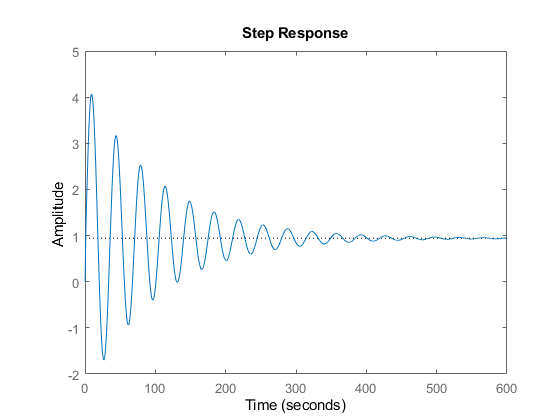

step(SS)



Am2=[-0.03 0.166 125.6  37.29;
    -0.052 -1.02 -1554.7 -427.82;
    0 0 0 1;
    0.128 -0.0142 -1335.49 -425.12];

Bm=[-138.1 1584.2 0 1361.6]';
Cm=[0 0 1 0];
Dm=0;

RM=ss(Am,Bm,Cm,Dm)

RM =
 
  A = 
            x1       x2
   x1    -0.03    0.166
   x2   -0.052    -1.02
   x3        0        0
   x4    0.128  -0.0142
 
            x3       x4
   x1    125.6    37.29
   x2    -1555   -427.8
   x3        0        1
   x4    -1335   -425.1
 
  B = 
           u1
   x1  -138.1
   x2    1584
   x3       0
   x4    1362
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



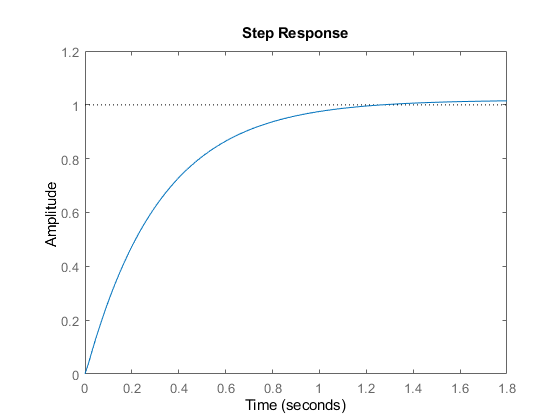

step(RM)

figure()
plot(out.al.time,out.al.signals.values)
title('Respuesta tren de pulsos')
legend({'\theta Modelo de referencia', '\theta Sistema'})
xlabel('time [s]') 
ylabel('Amplitude [°]') 

figure()
plot(out.error.time,out.error.signals.values)
title('Error de las variables de estado tren de pulsos')
legend({'e de u_x','e de u_z','e de \theta','e de q'})
xlabel('time [s]') 
ylabel('Amplitude') 

 krr=out.kr.signals.values;
 figure()
 i=1;
 hold on
 while i<= length(krr)
    plot(out.error.time(i),krr(:,:,i),'.r')
    i=i+1;
 end
 hold off
 title('K_r vs t')
%legend({'K_r'})
xlabel('time [s]') 
ylabel('Amplitude')

% figure()
% plot(out.kr.time,krn)
% title('K_r vs t')
% legend({'K_r'})
% xlabel('time [s]') 
% ylabel('Amplitude') 
figure()
plot(out.kx.time,out.kx.signals.values)
title('K_x vs t')
legend({'K_x(1)','K_x(2)','K_x(3)','K_x(4)'})
xlabel('time [s]') 
ylabel('Amplitude') 

kxf=[-0.0271047998014168	0.0124678830496998	316.284933192303	100.319652880918];
As=A-B*kxf


syms k1 k2 k3 k4
Ab=A-B*[k1 k2 k3 k4]

kx(1)=double(solve(Am(1,1)==Ab(1,1),k1))
double(solve(Am(2,1)==Ab(2,1),k1))
double(solve(Am(3,1)==Ab(3,1),k1))

kx(2)=double(solve(Am(1,2)==Ab(1,2),k2))
double(solve(Am(2,2)==Ab(2,2),k2))
double(solve(Am(3,2)==Ab(3,2),k2))

kx(3)=double(solve(Am(1,3)==Ab(1,3),k3))
double(solve(Am(2,3)==Ab(2,3),k3))
double(solve(Am(3,3)==Ab(3,3),k3))

kx(4)=double(solve(Am(1,4)==Ab(1,4),k4))
double(solve(Am(2,4)==Ab(2,4),k4))
double(solve(Am(3,4)==Ab(3,4),k4))

gamma= [1 0 0 0;
        0 1 0 0;
        0 0 1 0;
        0 0 0 1];

% %P=      [3 0 0 0;
%         0 3 0 0;
%         0 0 3 0;
%         0 0 0 3];

gammar=10;

Q=eye(4)*10
P=lyap(Am,Q)
det(P)


Bd=Bm./B;
kr=Bd(4,1)


$$e=x_{m\;} -x$$



$$\dot{e} =\dot{x_m \;} -\dot{\;x}$$



$$\dot{e} =A_m x_m +B_m u-\textrm{Ax}+\textrm{Bu}$$
